close all;
clear all;
color.code=colormap(slanCM(160));

@author : slandarer


color.l=length(color.code);
color.index{1}=round(color.l/9);
color.index{2}=round(color.l*2.5/9);
color.index{3}=round(color.l*4/9);
color.index{4}=round(color.l*5.5/9);
color.index{5}=round(color.l*7/9);
color.index{6}=round(color.l*8.5/9);
color.index{7}=round(color.l);
L=15.5/2;
l1=3.025/2;
r1=5.12/2;
H=7/2;
l3=1.5/2;
r2=4.5/2;
phi=deg2rad(45);
E=17E6;
%E2=2E9;
b=2;
h=0.68;
Iz=b*h^3/12;
des=1.29e-3;
lmd1=0.15;
lmd3=0.15;
%%K1
th0=solve_th0(L,lmd1,lmd3,H);
fct1=1;
fct2=1;
fct3=1;


[m2,m3]=calculate_mass(lmd1,lmd3,L,des,th0,b,h);
v=1/3;%%(mm/s)
dt=0.1;%%(s);
t=0:dt:24;
g=9800;%%(mm/s^2)
d=v*t;
l2=L*(1-lmd1-lmd3)/cos(th0);
th0=-th0;
const=0.4:2:12.4;
figure('DefaultAxesFontSize',17,'Position',[50 50 600 300])
for q=1:length(const)
    k1=solve_k1(const(q),l1,L,lmd1,E,Iz);
    k2=solve_k2(fct2,L,E,Iz,k1,lmd1,lmd3,H);
    k3=fct3*solve_k3(k1,k2,E,b,h,th0,lmd1,lmd3,l1,l3,r1,r2,phi,H,L,Iz)
    ratio=roundn(k3/k2,-2);
    ratio2=roundn(k1/k3,-2);
    F1=lagrange_approach(d,H,v,th0,dt,k1,k2,k3,m2,m3,l2,g,L);
    plot(d,F1,'Color',color.code(color.index{q},:),'LineWidth',2);
    str{q}=[num2str(ratio2)];
    hold on
end

k3 = 2.7367e+06

k3 = 2.7982e+06

k3 = 2.8520e+06

k3 = 2.9062e+06

k3 = 2.9605e+06

k3 = 3.0149e+06

k3 = 3.0692e+06

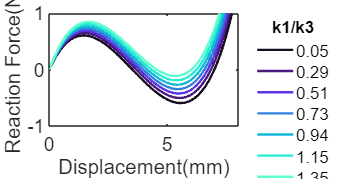

%title('k3/k2=',num2str(ratio)'');
lgd1=legend(str);
legend('boxoff');
legend('Location','northeastoutside','FontName','Arial');
xlabel('Displacement(mm)');
ylabel('Reaction Force(N)');
title(lgd1,'k1/k3');
axis([0 8 -1 1]);


figure('DefaultAxesFontSize',17,'Position',[50 50 600 300])
for q=1:length(const)
    k1=solve_k1(fct1,l1,L,lmd1,E,Iz);
    k2=solve_k2(fct2,L,E,Iz,k1,lmd1,lmd3,H);
    k3=const(q)*solve_k3(k1,k2,E,b,h,th0,lmd1,lmd3,l1,l3,r1,r2,phi,H,L,Iz)
    F2=lagrange_approach(d,H,v,th0,dt,k1,k2,k3,m2,m3,l2,g,L);
    plot(d,F2,'Color',color.code(color.index{q},:),'LineWidth',2);
    ratio=roundn(k1/k2,-2);
    ratio2=roundn(k3/k1,-2);
    str{q}=[num2str(ratio2)];
    hold on
end

k3 = 1.1056e+06

k3 = 6.6338e+06

k3 = 1.2162e+07

k3 = 1.7690e+07

k3 = 2.3218e+07

k3 = 2.8746e+07

k3 = 3.4274e+07

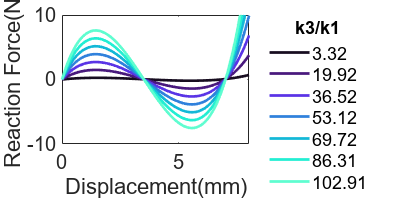

%title('k1/k3=',num2str(ratio));
lgd2=legend(str);
title(lgd2,'k3/k1');
legend('boxoff');
legend('Location','northeastoutside','FontName','Arial');
xlabel('Displacement(mm)');
ylabel('Reaction Force(N)');
axis([0 8 -10 10]);


figure('DefaultAxesFontSize',17,'Position',[50 50 600 300])
for q=1:length(const)
    k1=solve_k1(fct1,l1,L,lmd1,E,Iz);
    k2=const(q)*solve_k2(fct2,L,E,Iz,k1,lmd1,lmd3,H);
    k3=fct3*solve_k3(k1,k2,E,b,h,th0,lmd1,lmd3,l1,l3,r1,r2,phi,H,L,Iz)
    F3=lagrange_approach(d,H,v,th0,dt,k1,k2,k3,m2,m3,l2,g,L);
    plot(d,F3,'Color',color.code(color.index{q},:),'LineWidth',2);
    ratio=roundn(k1/k3,-2);
    ratio2=roundn(k2/k3,-4);
    str{q}=[num2str(ratio2)];
    hold on
end

k3 = 2.7594e+06

k3 = 2.7749e+06

k3 = 2.7904e+06

k3 = 2.8059e+06

k3 = 2.8214e+06

k3 = 2.8369e+06

k3 = 2.8524e+06

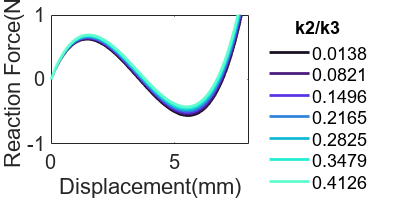

%title('k1/k2=',num2str(ratio));
lgd3=legend(str);
title(lgd3,'k2/k3');
legend('boxoff');
legend('Location','northeastoutside','FontName','Arial');
xlabel('Displacement(mm)');
ylabel('Reaction Force(N)');
axis([0 8 -1 1]);